# Static Equilibrium Analysis of a Double Wishbone Suspension

## Details

Name: George Poulter; Max Poulter

Email: GeorgePoulter27@gmail.com; MPoulter98@gmail.com

Version: V07

V01: 03/02/2021; First iteration

V02: 03/02/2021; Debugging

V03: 04/02/2021; Tyre toe angle added to figure

V04: 06/02/2020; Structure format for cleaner workspace. Khaled Ghobashy method added

V05: 09/02/2020; Method one and two output

V06: 11/02/2020; Vector equation updated in method one

V07: 23/10/2021: Upright force equations amended. Moment calculations inverted (S moments now negative) to make calculations work. Push vs Pull rod functionality added. TCP equation updated to work on rear. Camber and Toe now only for plotting. Method 2 deleted. 

## Analysis

The user should detail here what analysis is been performed. Please include:

- Richard Wade- rowade1@sheffield.ac.uk

- SFR12-VD-GEOM-V001

- Determining Load Cases

## Introduction

This code is developed for the purpose of analysing a double wishbone suspension system for the University of Sheffield's Formula Student, Sheffield Formula Racing (SFR). The reaction loads in each of the suspension members is calculated from a tyre contact patch (TCP) load.

The code has been adapted from that published by Adriano Schommer and Khaled Ghobashy. See the following respectively: [https://nbviewer.jupyter.org/github/adrianoschommer/static_equilibrium_suspension/blob/master/static_equilibrium_wishbone_suspension.ipynb](https://nbviewer.jupyter.org/github/adrianoschommer/static_equilibrium_suspension/blob/master/static_equilibrium_wishbone_suspension.ipynb)

[https://colab.research.google.com/drive/1ocX85lA8D8QYEIUGQGXfJZl3gwhWru7M?authuser=0&fbclid=IwAR2Zjpszmsz3ValUFyu5e4_HJA0PF1%E2%80%A6](https://colab.research.google.com/drive/1ocX85lA8D8QYEIUGQGXfJZl3gwhWru7M?authuser=0&fbclid=IwAR2Zjpszmsz3ValUFyu5e4_HJA0PF1%E2%80%A6) 

Both methods are also saved as PDF and are available on the team drive.

### Method One - Truss Analysis

The static equilibrium of a double wishbone suspension system can be solved by assuming it as a system of truss members. Here the geometry is defined by hardpoints at each of end of member. The analysis of trusses is usually based on the following assumptions:

- The centroidal axis of each member coincides with the line connection of each hard point and therefore the members only carry axial force

- All members are connected only at their ends by non-frictional hinges

- All load and support reactions are applied only at the joints

The purpose of these assumptions is to obtain an ideal truss system whereby a member is subject to only axial forces in the direction given by the unit vector of each link.

The approach for this tool uses spatial vector algebra to abstract and analyse the kinematics and kinetic aspects of the system. The user should familiarise themselves with vector mechanics. "Vector Mechanics for Engineers: Statics and Dynamics" is a good book.

The objective is to form a system of linear equations in the form $\textrm{Qr}=S$. These letters have been selected purely for clarity against other workspace variables. You would usually refer to this form as $\textrm{Ax}=B$. A system of linear equations is a collection of $n$ linear equations, involving the same set of up to $n$ variables. A solution to a linear system is obtained if all the equations are simultaneously satisfied.

For this analysis we will form six equations; one for each degree of freedom (DoF); $F_x$, $F_y$, $F_z$, $M_x$, $M_y$, $M_z$. For static equilibrium, the sum of forces (for DoF 1-3) and moments (for DoF 4-6) must equal zero.

As with normal automotive convention, the coordinate systems (CSYS) is cartesian with the origin in the car centreline, on the front axle and at ground. The $x$ axis is pointing rearwards, $y$ axis point rightwards and the $z$ axis pointing upwards.

All measurements given in mm, loads in N, and moments in Nmm unless otherwise specified.

### Method Two - Multibody Analysis

Method two follows that outlined in "The Multibody Systems Approach to Vehicle Dynamics" chapter four. The method uses a multibody approach. This allows load to be carried through the rigid bodies not along the direction of the members, as well as the taking into account the "daisy chain effect" of mounting the prod to the wishbones, not the upright. A constraint is imposed on one of the wishbone inboard mounts that results in a mislead force. Be wary when using these values.

The author suggest method one is the best approach. Method two is left in here to demonstrate the effect assumptions have on solutions. Bare in mind that these are both industrial accepted methods that yield some similar, and some dissimilar results.

## Initialise

clc % clear command windo
clear all % clear workspace
close all % close all windows

Q = zeros(6,6); % zero matrix
r = zeros(6,1); % zero vector
S = zeros(6,1); % zero vecotr

## Inputs

### Geometry

Please specify the system hard points. The free body diagram (FBD) below is defined by the points: $A$, $B$, $C$, $D$, $E$, $F$, $G$, $H$, $I$, $J$, $O$; where $O$ is the TCP which can be calculated using the wheel centre position, $K$ and the static camber angle.

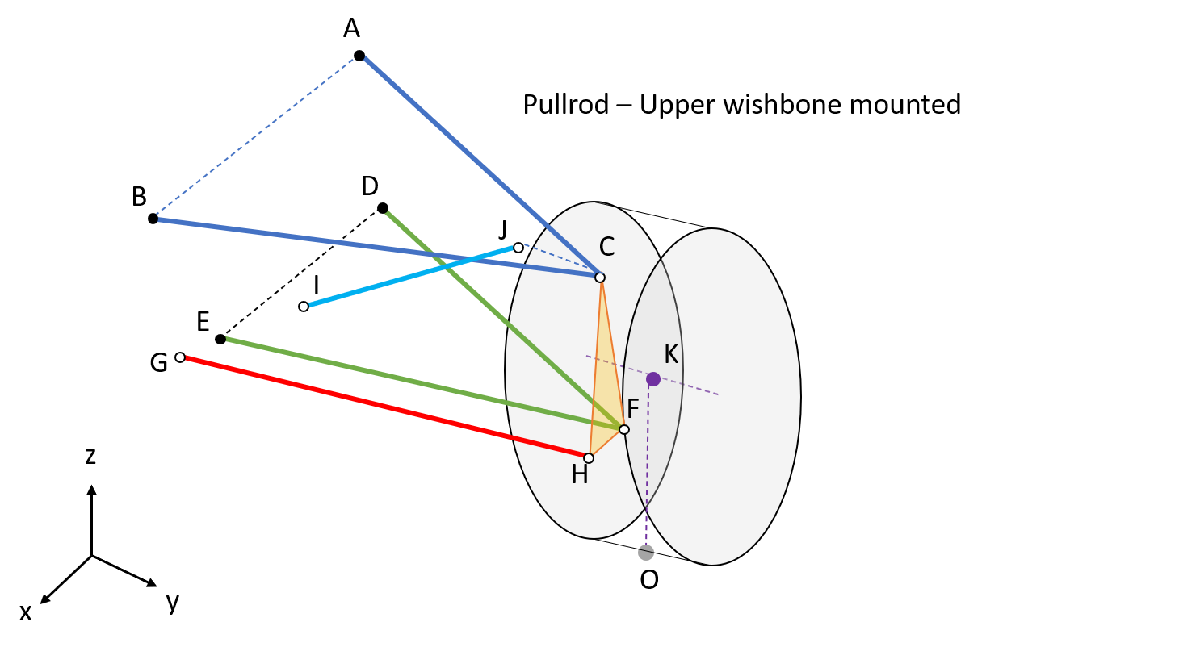

%static geom
Geom.F = [-3.5;-529 ;122.84]; % wishbone, lower, outboard
Geom.D = [-45;-190 ;129.9]; % wishbone, lower, outboard
Geom.E = [193;-232 ;129.7]; % wishbone, lower, outboard
Geom.C = [3.5;-522 ;282]; % wishbone, lower, outboard
Geom.A = [-85;-235 ;277.3]; % wishbone, lower, outboard
Geom.B = [193;-258 ;259.8]; % wishbone, lower, outboard
Geom.J = [3.5;-522 ;282]; % wishbone, lower, outboard
Geom.I = [1.15;-115.34 ;77.24]; % wishbone, lower, outboard
Geom.H = [-59.2;-544 ;133]; % wishbone, lower, outboard
Geom.G = [-73;-172 ;122]; % wishbone, lower, outboard
Geom.K = [-0.17;-576.74 ;197.44]; % wishbone, lower, outboard
Geom.Camber_Static = 0; % static camber angle [deg] just for graphics
Geom.Toe_Static = 0; % static toe angle. Pos inwards [deg] just for graphics
Geom.O = [Geom.K(1); Geom.K(2); 0]; % TCP

Geom.Tyre_Width = 152.4; % [mm] (6") this is purely for plotting purposes later
Geom.Tyre_Rad = Geom.K(3); % [mm] tyre radius

Geom.PRod_Type = 1; %1=pullrod, 2= pushrod;

### TCP Load

Please specify the load at the TCP in all six DoF: $F_x$, $F_y$, $F_z$, $M_x$, $M_y$ and $M_z$.

% cornering - right turn @ 28.5m/s and -2.31G aLat
% Tyre moments estimated from TTC data

TCP.F_x = 0; % N positive backwards
TCP.F_y = 0;% N positive right
TCP.F_z = 595; %N positive upwards  
TCP.M_x = 0; % Nmm positive counter clockwise  
TCP.M_y = 0; % Nmm positive counter clockwise
TCP.M_z = 0; % Nmm positive counter clockwise 

S = [TCP.F_x; TCP.F_y; TCP.F_z; -TCP.M_x; -TCP.M_y; -TCP.M_z]; % external force and moment vector

## Method One - Truss Analysis

### Unit Vectors

The direction of each member is given by the unit vectors: $\vec{u_1 }$, $\vec{u_2 }$, $\vec{u_2 }$, $\vec{u_3 }$, $\vec{u_4 }$, $\vec{u_5 }$.

If we consider the points $A$ and $C$ for now, we will define the unit vector between them $\vec{u_{\textrm{AC}} }$. Here, $\vec{u_{\textrm{AC}} }$ is simply the vector $\vec{\textrm{AC}}$ divided by its magnitude (or Euclidian norm) $\left|\textrm{AC}\right|$.


$$\vec{u_{\textrm{AC}} } =\frac{\vec{\textrm{AC}} }{\left|\textrm{AC}\right|}$$


Vect.AC = Geom.C - Geom.A; % vector AC, wishbone upper front
Vect.BC = Geom.C - Geom.B; % vector BC, wishbone upper rear
Vect.DF = Geom.F - Geom.D; % vector DF, wishbone lower front
Vect.EF = Geom.F - Geom.E; % vector EF, wishbone lower rear
Vect.GH = Geom.H - Geom.G; % vector GH, trackrod
Vect.IJ = Geom.J - Geom.I; % vector IG, pushrod

Vect.u_AC = Vect.AC/ norm(Vect.AC); % unit vector AC, wishbone upper front
Vect.u_BC = Vect.BC/ norm(Vect.BC); % unit vector BC, wishbone upper rear
Vect.u_DF = Vect.DF/ norm(Vect.DF); % unit vector DF, wishbone lower front
Vect.u_EF = Vect.EF/ norm(Vect.EF); % unit vector EF, wishbone lower rear
Vect.u_GH = Vect.GH/ norm(Vect.GH); % unit vector GH, trackrod
Vect.u_IJ = Vect.IJ/ norm(Vect.IJ); % unit vector IJ, pushrod

### Forming the Q Matrix: Rows 1-3

The first three rows of the $Q$ matrix are fairly straight forward. As we mentioned previously, the first three rows concern themselves with the forces in the principal directions $x$, $y$ and $z$. We have assumed the members are carrying reaction loads only in the direction of their respective unit vector. These loads are donated $R_{\textrm{AC}}$, $R_{\textrm{BC}}$, $R_{\textrm{DF}}$, $R_{\textrm{EF}}$, $R_{\textrm{GH}}$, $R_{\textrm{IJ}}$. These are scalar objects.

To calculate each of the principal components of each reaction load you can simply multiply the reaction load by the unit vector. 

Let us look at member $\textrm{AC}$ again. If we multiply $R_{\textrm{AC}}$ by $\vec{u_{\textrm{AC}} }$ we will return a column vector containing the components of $R_{\textrm{AC}}$ in each direction.


$$R_{\textrm{AC}} \vec{u_{\textrm{AC}} } =R_{\textrm{AC}} \left\lbrack \begin{array}{c}
u_{\textrm{AC},x} \\
u_{\textrm{AC},y} \\
u_{\textrm{AC},z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
R_{\textrm{AC},x} \\
R_{\textrm{AC},y} \\
R_{\textrm{AC},z} 
\end{array}\right\rbrack$$


Taking this method for all the members, our linear system looks like this so far


$$\left\lbrack \begin{array}{cccccc}
u_{\textrm{AC},x}  & u_{\textrm{BC},x}  & u_{\textrm{DF},x}  & u_{\textrm{EF},x}  & u_{\textrm{GH},x}  & u_{\textrm{IJ},x} \\
u_{\textrm{AC},y}  & u_{\textrm{BC},y}  & u_{\textrm{DF},y}  & u_{\textrm{EF},y}  & u_{\textrm{GH},y}  & u_{\textrm{IJ},y} \\
u_{\textrm{AC},z}  & u_{\textrm{BC},z}  & u_{\textrm{DF},z}  & u_{\textrm{EF},z}  & u_{\textrm{GH},z}  & u_{\textrm{IJ},z} \\
- & - & - & - & - & -\\
- & - & - & - & - & -\\
- & - & - & - & - & -
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
R_{\textrm{AC}} \\
R_{\textrm{BC}} \\
R_{\textrm{DF}} \\
R_{\textrm{EF}} \\
R_{\textrm{GH}} \\
R_{\textrm{IJ}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
F_x \\
F_y \\
F_z \\
M_x \\
M_y \\
M_z 
\end{array}\right\rbrack$$


Q(1:3, 1) = Vect.u_AC; % rows 1 to 3 in column 1
Q(1:3, 2) = Vect.u_BC; % rows 1 to 3 in column 2
Q(1:3, 3) = Vect.u_DF; % rows 1 to 3 in column 3
Q(1:3, 4) = Vect.u_EF; % rows 1 to 3 in column 4
Q(1:3, 5) = Vect.u_GH; % rows 1 to 3 in column 5
Q(1:3, 6) = Vect.u_IJ; % rows 1 to 3 in column 6

### Forming the Q Matrix: Rows 4-6

The final three rows of the $Q$ matrix are given by components of the moment arm of the forces applied to an arbitrary point at which the moments are balanced; in our case the TCP. Remember that the moment caused by a given force around an axis is the magnitude of the force multiplied by the perpendicular distance to that axis. 

Let us again consider member $\textrm{AC}$. We want to find the $x$, $y$ and $z$ components of the moment caused by $R_{\textrm{AC}}$ around the TCP, $O$. Once one understands vector mechanics this again is fairly simple. The moment vector is simply the cross product between the vector $\overset{\longrightarrow }{\textrm{AO}}$ and the force vector $\left\lbrace R_{\textrm{AC}} \vec{u_{\textrm{AC}} } \right\rbrace$


$$M_O =\overset{\longrightarrow }{\textrm{AO}} \times \left\lbrace R_{\textrm{AC}} \vec{u_{\textrm{AC}} } \right\rbrace =R_{\textrm{AC}} \left\lbrace \overset{\longrightarrow }{\textrm{AO}} \times \vec{u_{\textrm{AC}} } \right\rbrace$$


So, we need to define some more vectors:$\overset{\longrightarrow }{\textrm{AO}}$,  $\overset{\longrightarrow }{\textrm{BO}}$, $\overset{\longrightarrow }{\textrm{DO}}$, $\overset{\longrightarrow }{\textrm{EO}}$, $\overset{\longrightarrow }{\textrm{GO}}$ and $\overset{\longrightarrow }{\textrm{IO}}$

Vect.AO = Geom.O - Geom.A; % vector AO
Vect.BO = Geom.O - Geom.B; % vector BO
Vect.DO = Geom.O - Geom.D; % vector DO
Vect.EO = Geom.O - Geom.E; % vector EO
Vect.GO = Geom.O - Geom.G; % vector GO
Vect.IO = Geom.O - Geom.I; % vector IO

Taking this method for all of our members, our linear system now looks like this


$$\left\lbrack \begin{array}{cccccc}
u_{\textrm{AC},x}  & u_{\textrm{BC},x}  & u_{\textrm{DF},x}  & u_{\textrm{EF},x}  & u_{\textrm{GH},x}  & u_{\textrm{IJ},x} \\
u_{\textrm{AC},y}  & u_{\textrm{BC},y}  & u_{\textrm{DF},y}  & u_{\textrm{EF},y}  & u_{\textrm{GH},y}  & u_{\textrm{IJ},y} \\
u_{\textrm{AC},z}  & u_{\textrm{BC},z}  & u_{\textrm{DF},z}  & u_{\textrm{EF},z}  & u_{\textrm{GH},z}  & u_{\textrm{IJ},z} \\
{\left\lbrace \overset{\longrightarrow }{\textrm{AO}} \times \vec{u_{\textrm{AC}} } \right\rbrace }_x  & {\left\lbrace \overset{\longrightarrow }{\textrm{BO}} \times \vec{u_{\textrm{BC}} } \right\rbrace }_x  & {\left\lbrace \overset{\longrightarrow }{\textrm{DO}} \times \vec{u_{\textrm{DF}} } \right\rbrace }_x  & {\left\lbrace \overset{\longrightarrow }{\textrm{EO}} \times \vec{u_{\textrm{EF}} } \right\rbrace }_x  & {\left\lbrace \overset{\longrightarrow }{\textrm{GO}} \times \vec{u_{\textrm{GH}} } \right\rbrace }_x  & {\left\lbrace \overset{\longrightarrow }{\textrm{IO}} \times \vec{u_{\textrm{IJ}} } \right\rbrace }_x \\
{\left\lbrace \overset{\longrightarrow }{\textrm{AO}} \times \vec{u_{\textrm{AC}} } \right\rbrace }_y  & {\left\lbrace \overset{\longrightarrow }{\textrm{BO}} \times \vec{u_{\textrm{BC}} } \right\rbrace }_y  & {\left\lbrace \overset{\longrightarrow }{\textrm{DO}} \times \vec{u_{\textrm{DF}} } \right\rbrace }_y  & {\left\lbrace \overset{\longrightarrow }{\textrm{EO}} \times \vec{u_{\textrm{EF}} } \right\rbrace }_y  & {\left\lbrace \overset{\longrightarrow }{\textrm{GO}} \times \vec{u_{\textrm{GH}} } \right\rbrace }_y  & {\left\lbrace \overset{\longrightarrow }{\textrm{IO}} \times \vec{u_{\textrm{IJ}} } \right\rbrace }_y \\
{\left\lbrace \overset{\longrightarrow }{\textrm{AO}} \times \vec{u_{\textrm{AC}} } \right\rbrace }_z  & {\left\lbrace \overset{\longrightarrow }{\textrm{BO}} \times \vec{u_{\textrm{BC}} } \right\rbrace }_z  & {\left\lbrace \overset{\longrightarrow }{\textrm{DO}} \times \vec{u_{\textrm{DF}} } \right\rbrace }_z  & {\left\lbrace \overset{\longrightarrow }{\textrm{EO}} \times \vec{u_{\textrm{EF}} } \right\rbrace }_z  & {\left\lbrace \overset{\longrightarrow }{\textrm{GO}} \times \vec{u_{\textrm{GH}} } \right\rbrace }_z  & {\left\lbrace \overset{\longrightarrow }{\textrm{IO}} \times \vec{u_{\textrm{IJ}} } \right\rbrace }_z 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
R_{\textrm{AC}} \\
R_{\textrm{BC}} \\
R_{\textrm{DF}} \\
R_{\textrm{EF}} \\
R_{\textrm{GH}} \\
R_{\textrm{IJ}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
F_x \\
F_y \\
F_z \\
M_x \\
M_y \\
M_z 
\end{array}\right\rbrack$$


Vect.um_AC = cross(Vect.AO, Vect.u_AC); % unit moment AC, wishbone upper front
Vect.um_BC = cross(Vect.BO, Vect.u_BC); % unit moment BC, wishbone upper rear
Vect.um_DF = cross(Vect.DO, Vect.u_DF); % unit moment DF, wishbone lower front
Vect.um_EF = cross(Vect.EO, Vect.u_EF); % unit moment EF, wishbone lower rear
Vect.um_GH = cross(Vect.GO, Vect.u_GH); % unit moment GH, trackrod
Vect.um_IJ = cross(Vect.IO, Vect.u_IJ); % unit moment IJ, pushrod

Next lets update the $Q$ matrix with these unit moments

Q(4:6, 1) = Vect.um_AC; % rows 4 to 6 in column 1
Q(4:6, 2) = Vect.um_BC; % rows 4 to 6 in column 2
Q(4:6, 3) = Vect.um_DF; % rows 4 to 6 in column 3
Q(4:6, 4) = Vect.um_EF; % rows 4 to 6 in column 4
Q(4:6, 5) = Vect.um_GH; % rows 4 to 6 in column 5
Q(4:6, 6) = Vect.um_IJ; % rows 4 to 6 in column 6

### Solving

We have now formed our system of linear equations $\textrm{Qr}=S$ where $r$ is our unknown $6\times 1$ vector. This is easy to solve with MATLAB using the mldivide function.

r=mldivide(Q,S); % solving the linear system Qr=S

%values are in the direction of the unit vector, i.e. inboard to outboard
%(so positie values are in tension)
R.AC = r(1); % scalar force AC
R.BC = r(2); % scalar force BC
R.DF = r(3); % scalar force DF
R.EF = r(4); % scalar force EF
R.GH = r(5); % scalar force GH
R.IJ = r(6); % scalar force IJ

%the load component applied to the element at the OB point 
F.AC = R.AC * Vect.u_AC; % vector force AC
F.BC = R.BC * Vect.u_BC; % vector force BC
F.DF = R.DF * Vect.u_DF; % vector force DF
F.EF = R.EF * Vect.u_EF; % vector force EF
F.GH = R.GH * Vect.u_GH; % vector force GH
F.IJ = R.IJ * Vect.u_IJ; % vector force IJ

## Output Method One Results

Method1.Load_Case = S;

%loads in the elements (acting in global coordinate system)
Method1.Vector_Force.Wishbone_Upper_Front = F.AC;
Method1.Vector_Force.Wishbone_Upper_Rear = F.BC;
Method1.Vector_Force.Wishbone_Lower_Front = F.DF;
Method1.Vector_Force.Wishbone_Lower_Rear = F.EF;
Method1.Vector_Force.Trackrod = F.GH;
Method1.Vector_Force.PRod = F.IJ;

%loads in the upright, which are the reaction of the elements (acting in global coordinate system)
Method1.Vector_Force.Upright_Trackrod = -(F.GH); %load applied to upright from trackrod 
if Geom.PRod_Type == 1
    Method1.Vector_Force.Upright_Lower = -(F.DF + F.EF); %load applied to upright from wishbones
    Method1.Vector_Force.Upright_Upper = -(S(1:3,:) + Method1.Vector_Force.Upright_Lower + Method1.Vector_Force.Upright_Trackrod);
elseif Geom.PRod_Type == 2
    Method1.Vector_Force.Upright_Upper = -(F.AC + F.BC);
    Method1.Vector_Force.Upright_Lower = -(S(1:3,:) + Method1.Vector_Force.Upright_Upper + Method1.Vector_Force.Upright_Trackrod); %load applied to upright from wishbones
end

Method1.Scalar_Force.Wishbone_Upper_Front = R.AC;
Method1.Scalar_Force.Wishbone_Upper_Rear = R.BC;
Method1.Scalar_Force.Wishbone_Lower_Front = R.DF;
Method1.Scalar_Force.Wishbone_Lower_Rear = R.EF;
Method1.Scalar_Force.Trackrod = R.GH;
Method1.Scalar_Force.PRod = R.IJ;
Method1.Scalar_Force.Upright_Trackrod = norm(Method1.Vector_Force.Upright_Trackrod);
Method1.Scalar_Force.Upright_Upper = norm(Method1.Vector_Force.Upright_Upper);
Method1.Scalar_Force.Upright_Lower = norm(Method1.Vector_Force.Upright_Lower);
outputMatrix = [Method1.Vector_Force.Upright_Lower(1,1) Method1.Vector_Force.Upright_Lower(2,1) Method1.Vector_Force.Upright_Lower(3,1) Method1.Scalar_Force.Upright_Lower
    ; Method1.Vector_Force.Wishbone_Lower_Front(1,1) Method1.Vector_Force.Wishbone_Lower_Front(2,1) Method1.Vector_Force.Wishbone_Lower_Front(3,1) R.DF
    ; Method1.Vector_Force.Wishbone_Lower_Rear(1,1) Method1.Vector_Force.Wishbone_Lower_Rear(2,1) Method1.Vector_Force.Wishbone_Lower_Rear(3,1) R.EF
    ; Method1.Vector_Force.Upright_Upper(1,1) Method1.Vector_Force.Upright_Upper(2,1) Method1.Vector_Force.Upright_Upper(3,1) Method1.Scalar_Force.Upright_Upper
    ; Method1.Vector_Force.Wishbone_Upper_Front(1,1) Method1.Vector_Force.Wishbone_Upper_Front(2,1) Method1.Vector_Force.Wishbone_Upper_Front(3,1) R.AC
    ; Method1.Vector_Force.Wishbone_Upper_Rear(1,1) Method1.Vector_Force.Wishbone_Upper_Rear(2,1) Method1.Vector_Force.Wishbone_Upper_Rear(3,1) R.BC
    ; Method1.Vector_Force.PRod(1,1) Method1.Vector_Force.PRod(2,1) Method1.Vector_Force.PRod(3,1) R.IJ
    ; Method1.Vector_Force.Trackrod(1,1) Method1.Vector_Force.Trackrod(2,1) Method1.Vector_Force.Trackrod(3,1) R.GH];

## Plotting

### Tyre Geometry

We need some tyre geometry to plot it in 3D before we can plot a figure of the system

Geom.Wheel_rot = [cosd(Geom.Toe_Static), -cosd(-Geom.Camber_Static)*sind(Geom.Toe_Static), sind(-Geom.Camber_Static)*sind(Geom.Toe_Static) ; ...
    sind(Geom.Toe_Static), cosd(-Geom.Camber_Static)*cosd(Geom.Toe_Static), -sind(-Geom.Camber_Static)*cosd(Geom.Toe_Static) ; ...
    0, sind(-Geom.Camber_Static), cosd(-Geom.Camber_Static)]; % Euler rotation - ZYX body fixed

Geom.Wheel_C_I = [Geom.Wheel_rot * [0 ; -Geom.Tyre_Width/2; 0] + [Geom.K(1); Geom.K(2); Geom.K(3)]]'; % tyre centre inboard
Geom.Wheel_C_O = [Geom.Wheel_rot * [0 ; + Geom.Tyre_Width/2; 0] + [Geom.K(1); Geom.K(2); Geom.K(3)]]'; % tyre centre inboard

Geom.Wheel_Axis = (Geom.Wheel_C_O - Geom.Wheel_C_I)/ norm(Geom.Wheel_C_O - Geom.Wheel_C_I); % unit vector of wheel axis
Geom.Tyre_I = Circle3D(Geom.Wheel_C_I, Geom.Wheel_Axis, Geom.Tyre_Rad); % Tyre inbaord
Geom.Tyre_O = Circle3D(Geom.Wheel_C_O, Geom.Wheel_Axis, Geom.Tyre_Rad); % Tyre outbaord

### Figure

Figure to show the system

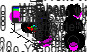

figure('Name','Geometry'); % create a new figure with a name
set(0, 'DefaultLineLineWidth', 2) % default line width to 2

subplot(3, 4, [1, 2, 3, 5, 6, 7, 9, 10, 11]) % isometric view plot
hold on % hold on to plot more on the same graph
plot3([Geom.A(1), Geom.C(1), Geom.B(1)], [Geom.A(2), Geom.C(2), Geom.B(2)], [Geom.A(3), Geom.C(3), Geom.B(3)], '-b', 'DisplayName', 'Wishbone Upper') % wishbone upper
plot3([Geom.D(1), Geom.F(1), Geom.E(1)], [Geom.D(2), Geom.F(2), Geom.E(2)], [Geom.D(3), Geom.F(3), Geom.E(3)], '-g', 'DisplayName', 'Wishbone Lower') % wishbone lower
plot3([Geom.G(1), Geom.H(1)], [Geom.G(2), Geom.H(2)], [Geom.G(3), Geom.H(3)], '-r', 'DisplayName', 'Trackrod') % trackrod
plot3([Geom.I(1), Geom.J(1)], [Geom.I(2), Geom.J(2)], [Geom.I(3), Geom.J(3)], '-c', 'DisplayName', 'PRod') % prod
plot3(Geom.O(1), Geom.O(2), Geom.O(3), '.m', 'MarkerSize', 30, 'DisplayName', 'Tyre Contact Patch') % TCP
fill3([Geom.C(1), Geom.F(1), Geom.H(1), Geom.C(1)], [Geom.C(2), Geom.F(2), Geom.H(2), Geom.C(2)], [Geom.C(3), Geom.F(3), Geom.H(3), Geom.C(3)], [1 0.35 0], 'facealpha', 0.5, 'DisplayName', 'Upright') % upright surface
plot3([Geom.A(1), Geom.B(1), Geom.C(1), Geom.D(1), Geom.E(1), Geom.F(1), Geom.G(1), Geom.H(1), Geom.I(1), Geom.J(1)], [Geom.A(2), Geom.B(2), Geom.C(2), Geom.D(2), Geom.E(2), Geom.F(2), Geom.G(2), Geom.H(2), Geom.I(2), Geom.J(2)], [Geom.A(3), Geom.B(3), Geom.C(3), Geom.D(3), Geom.E(3), Geom.F(3), Geom.G(3), Geom.H(3), Geom.I(3), Geom.J(3)], '.k', 'MarkerSize', 30, 'HandleVisibility', 'off') % points

fill3(Geom.Tyre_I(1,:), Geom.Tyre_I(2,:), Geom.Tyre_I(3,:), 'k', 'facealpha', 0.3, 'DisplayName', 'Tyre') % inner tyre wall
fill3(Geom.Tyre_O(1,:), Geom.Tyre_O(2,:), Geom.Tyre_O(3,:), 'k', 'facealpha', 0.3, 'HandleVisibility', 'off') % outer tyre wall
surf([Geom.Tyre_I(1,:); Geom.Tyre_O(1,:)], [Geom.Tyre_I(2,:); Geom.Tyre_O(2,:)], [Geom.Tyre_I(3,:); Geom.Tyre_O(3,:)], 'FaceColor', 'k', 'facealpha', 0.3, 'EdgeColor', 'none', 'HandleVisibility', 'off') % tyre circumference

hold off % stop holding on
    
xlabel('X Coordinate [mm]') % add x axis label
ylabel('Y Coordinate [mm]') % add y axis label
zlabel('Z Coordinate [mm]') % add z axis label
zlim([0 inf]) % z limit zero to infity
    
grid on % add minor grid
legend('Location', 'best'); % add legend
view(3); % default view for 3D figures (azimuth = -37.5 and elevation = 30)
daspect([1 1 1]) % lock the data aspect ratio

subplot(3, 4, 4) % front view plot
hold on % hold on to plot more on the same graph
plot3([Geom.A(1), Geom.C(1), Geom.B(1)], [Geom.A(2), Geom.C(2), Geom.B(2)], [Geom.A(3), Geom.C(3), Geom.B(3)], '-b', 'DisplayName', 'Wishbone Upper')
plot3([Geom.D(1), Geom.F(1), Geom.E(1)], [Geom.D(2), Geom.F(2), Geom.E(2)], [Geom.D(3), Geom.F(3), Geom.E(3)], '-g', 'DisplayName', 'Wishbone Lower')
plot3([Geom.G(1), Geom.H(1)], [Geom.G(2), Geom.H(2)], [Geom.G(3), Geom.H(3)], '-r', 'DisplayName', 'Trackrod')
plot3([Geom.I(1), Geom.J(1)], [Geom.I(2), Geom.J(2)], [Geom.I(3), Geom.J(3)], '-c', 'DisplayName', 'PRod')
plot3(Geom.O(1), Geom.O(2), Geom.O(3), '.m', 'MarkerSize', 20, 'DisplayName', 'Tyre Contact Patch')
fill3([Geom.C(1), Geom.F(1), Geom.H(1), Geom.C(1)], [Geom.C(2), Geom.F(2), Geom.H(2), Geom.C(2)], [Geom.C(3), Geom.F(3), Geom.H(3), Geom.C(3)], [1 0.35 0], 'facealpha', 0.5, 'DisplayName', 'Upright')
plot3([Geom.A(1), Geom.B(1), Geom.C(1), Geom.D(1), Geom.E(1), Geom.F(1), Geom.G(1), Geom.H(1), Geom.I(1), Geom.J(1)], [Geom.A(2), Geom.B(2), Geom.C(2), Geom.D(2), Geom.E(2), Geom.F(2), Geom.G(2), Geom.H(2), Geom.I(2), Geom.J(2)], [Geom.A(3), Geom.B(3), Geom.C(3), Geom.D(3), Geom.E(3), Geom.F(3), Geom.G(3), Geom.H(3), Geom.I(3), Geom.J(3)], '.k', 'MarkerSize', 20, 'HandleVisibility', 'off')

fill3(Geom.Tyre_I(1,:), Geom.Tyre_I(2,:), Geom.Tyre_I(3,:), 'k', 'facealpha', 0.3, 'DisplayName', 'Tyre') % inner tyre wall
fill3(Geom.Tyre_O(1,:), Geom.Tyre_O(2,:), Geom.Tyre_O(3,:), 'k', 'facealpha', 0.3, 'HandleVisibility', 'off') % outer tyre wall
surf([Geom.Tyre_I(1,:); Geom.Tyre_O(1,:)], [Geom.Tyre_I(2,:); Geom.Tyre_O(2,:)], [Geom.Tyre_I(3,:); Geom.Tyre_O(3,:)], 'FaceColor', 'k', 'facealpha', 0.3, 'EdgeColor', 'none', 'HandleVisibility', 'off') % tyre cirfumference

hold off % stop holding on
    
xlabel('X Coordinate [mm]') % add x axis label
ylabel('Y Coordinate [mm]') % add y axis label
zlabel('Z Coordinate [mm]') % add z axis label
zlim([0 inf]) % z limit zero to infity
    
grid on % add minor grid
view(270,0); % azimuth and elevation angle
daspect([1 1 1]) % lock the data aspect ratio
title('Front View') % add title

subplot(3, 4, 8) % plan view plot
hold on % hold on to plot more on the same graph
plot3([Geom.A(1), Geom.C(1), Geom.B(1)], [Geom.A(2), Geom.C(2), Geom.B(2)], [Geom.A(3), Geom.C(3), Geom.B(3)], '-b', 'DisplayName', 'Wishbone Upper') % wishbone upper
plot3([Geom.D(1), Geom.F(1), Geom.E(1)], [Geom.D(2), Geom.F(2), Geom.E(2)], [Geom.D(3), Geom.F(3), Geom.E(3)], '-g', 'DisplayName', 'Wishbone Lower') % wishbone lower
plot3([Geom.G(1), Geom.H(1)], [Geom.G(2), Geom.H(2)], [Geom.G(3), Geom.H(3)], '-r', 'DisplayName', 'Trackrod') % trackrod
plot3([Geom.I(1), Geom.J(1)], [Geom.I(2), Geom.J(2)], [Geom.I(3), Geom.J(3)], '-c', 'DisplayName', 'PRod') % prod
plot3(Geom.O(1), Geom.O(2), Geom.O(3), '.m', 'MarkerSize', 20, 'DisplayName', 'Tyre Contact Patch') % TCP
fill3([Geom.C(1), Geom.F(1), Geom.H(1), Geom.C(1)], [Geom.C(2), Geom.F(2), Geom.H(2), Geom.C(2)], [Geom.C(3), Geom.F(3), Geom.H(3), Geom.C(3)], [1 0.35 0], 'facealpha', 0.5, 'DisplayName', 'Upright') % upright surface
plot3([Geom.A(1), Geom.B(1), Geom.C(1), Geom.D(1), Geom.E(1), Geom.F(1), Geom.G(1), Geom.H(1), Geom.I(1), Geom.J(1)], [Geom.A(2), Geom.B(2), Geom.C(2), Geom.D(2), Geom.E(2), Geom.F(2), Geom.G(2), Geom.H(2), Geom.I(2), Geom.J(2)], [Geom.A(3), Geom.B(3), Geom.C(3), Geom.D(3), Geom.E(3), Geom.F(3), Geom.G(3), Geom.H(3), Geom.I(3), Geom.J(3)], '.k', 'MarkerSize', 30, 'HandleVisibility', 'off') % points

fill3(Geom.Tyre_I(1,:), Geom.Tyre_I(2,:), Geom.Tyre_I(3,:), 'k', 'facealpha', 0.3, 'DisplayName', 'Tyre') % inner tyre wall
fill3(Geom.Tyre_O(1,:), Geom.Tyre_O(2,:), Geom.Tyre_O(3,:), 'k', 'facealpha', 0.3, 'HandleVisibility', 'off') % outer tyre wall
surf([Geom.Tyre_I(1,:); Geom.Tyre_O(1,:)], [Geom.Tyre_I(2,:); Geom.Tyre_O(2,:)], [Geom.Tyre_I(3,:); Geom.Tyre_O(3,:)], 'FaceColor', 'k', 'facealpha', 0.3, 'EdgeColor', 'none', 'HandleVisibility', 'off') % tyre circumference

hold off % stop holding on
    
xlabel('X Coordinate [mm]') % add x axis label
ylabel('Y Coordinate [mm]') % add y axis label
zlabel('Z Coordinate [mm]') % add z axis label
zlim([0 inf]) % z limit zero to infity
    
grid on % add minor grid
view(270, 90); % azimuth and elevation angle
daspect([1 1 1]) % lock the data aspect ratio
title('Plan View') % add title

subplot(3, 4, 12) % inside view plot
hold on % hold on to plot more on the same graph
hold on % hold on to plot more on the same graph
plot3([Geom.A(1), Geom.C(1), Geom.B(1)], [Geom.A(2), Geom.C(2), Geom.B(2)], [Geom.A(3), Geom.C(3), Geom.B(3)], '-b', 'DisplayName', 'Wishbone Upper') % wishbone upper
plot3([Geom.D(1), Geom.F(1), Geom.E(1)], [Geom.D(2), Geom.F(2), Geom.E(2)], [Geom.D(3), Geom.F(3), Geom.E(3)], '-g', 'DisplayName', 'Wishbone Lower') % wishbone lower
plot3([Geom.G(1), Geom.H(1)], [Geom.G(2), Geom.H(2)], [Geom.G(3), Geom.H(3)], '-r', 'DisplayName', 'Trackrod') % trackrod
plot3([Geom.I(1), Geom.J(1)], [Geom.I(2), Geom.J(2)], [Geom.I(3), Geom.J(3)], '-c', 'DisplayName', 'PRod') % prod
plot3(Geom.O(1), Geom.O(2), Geom.O(3), '.m', 'MarkerSize', 20, 'DisplayName', 'Tyre Contact Patch') % TCP
fill3([Geom.C(1), Geom.F(1), Geom.H(1), Geom.C(1)], [Geom.C(2), Geom.F(2), Geom.H(2), Geom.C(2)], [Geom.C(3), Geom.F(3), Geom.H(3), Geom.C(3)], [1 0.35 0], 'facealpha', 0.5, 'DisplayName', 'Upright') % upright surface
plot3([Geom.A(1), Geom.B(1), Geom.C(1), Geom.D(1), Geom.E(1), Geom.F(1), Geom.G(1), Geom.H(1), Geom.I(1), Geom.J(1)], [Geom.A(2), Geom.B(2), Geom.C(2), Geom.D(2), Geom.E(2), Geom.F(2), Geom.G(2), Geom.H(2), Geom.I(2), Geom.J(2)], [Geom.A(3), Geom.B(3), Geom.C(3), Geom.D(3), Geom.E(3), Geom.F(3), Geom.G(3), Geom.H(3), Geom.I(3), Geom.J(3)], '.k', 'MarkerSize', 30, 'HandleVisibility', 'off') % points

fill3(Geom.Tyre_I(1,:), Geom.Tyre_I(2,:), Geom.Tyre_I(3,:), 'k', 'facealpha', 0.3, 'DisplayName', 'Tyre') % inner tyre wall
fill3(Geom.Tyre_O(1,:), Geom.Tyre_O(2,:), Geom.Tyre_O(3,:), 'k', 'facealpha', 0.3, 'HandleVisibility', 'off') % outer tyre wall
surf([Geom.Tyre_I(1,:); Geom.Tyre_O(1,:)], [Geom.Tyre_I(2,:); Geom.Tyre_O(2,:)], [Geom.Tyre_I(3,:); Geom.Tyre_O(3,:)], 'FaceColor', 'k', 'facealpha', 0.3, 'EdgeColor', 'none', 'HandleVisibility', 'off') % tyre circumference

hold off % stop holding on
    
xlabel('X Coordinate [mm]') % add x axis label
ylabel('Y Coordinate [mm]') % add y axis label
zlabel('Z Coordinate [mm]') % add z axis label
zlim([0 inf]) % z limit zero to infity
    
grid on % add minor grid
view(0,0); % azimuth and elevation angle
daspect([1 1 1]) % lock the data aspect ratio
title('Inside View') % add title

## Clean Workspace

%clearvars -except Method1 Method2

## Functions

Functions must got at the end. These are not saved separately just for ease of use.

### Circle3D

The following function is used for plotting the wheel in 3D. It creates a circle of points in 3D space.

function [points] = Circle3D(center, normal, radius)
theta=0 : 0.1 : 2*pi;
v = null(normal);
points = repmat(center', 1, size(theta, 2)) + radius*(v(:,1)*cos(theta)+v(:,2)*sin(theta));
points = [points, points(:,1)];
end